Question 4 :

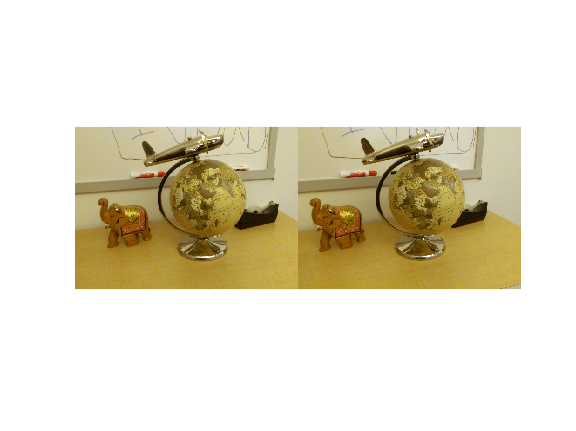

I1 = imread('I1op.bmp');
I2 = imread('I2op.bmp');

figure;
imshowpair(I1, I2, 'montage');

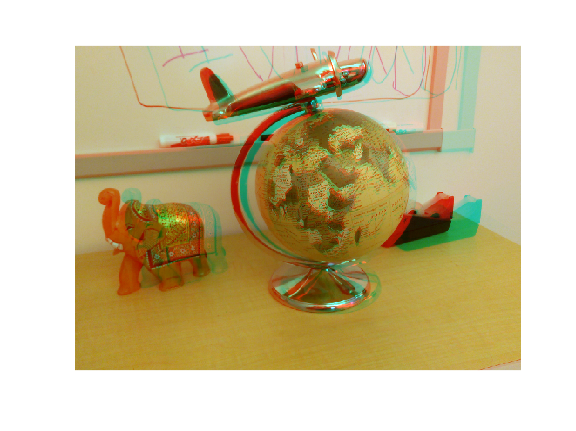


figure;
imshow(stereoAnaglyph(I1, I2));

Question 5 :

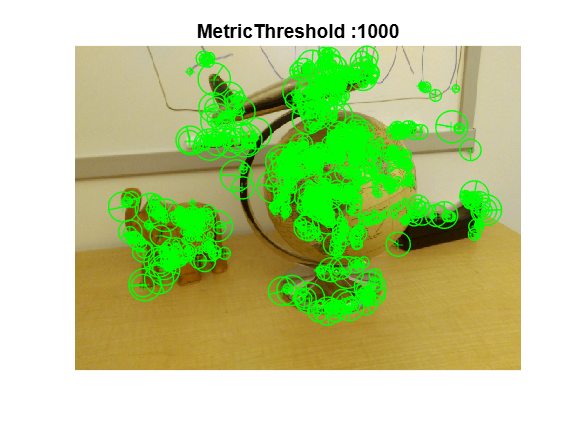

threshold = 1000;

corners1 = detectSURFFeatures(rgb2gray(I1), 'MetricThreshold', threshold);
[features1, valid_corners1] = extractFeatures(rgb2gray(I1), corners1);

figure;
imshow(I1);
hold on;
plot(valid_corners1, 'showOrientation', true); % 'true' displays feature orientations
title(strcat('MetricThreshold : ',num2str(threshold)));
hold off;

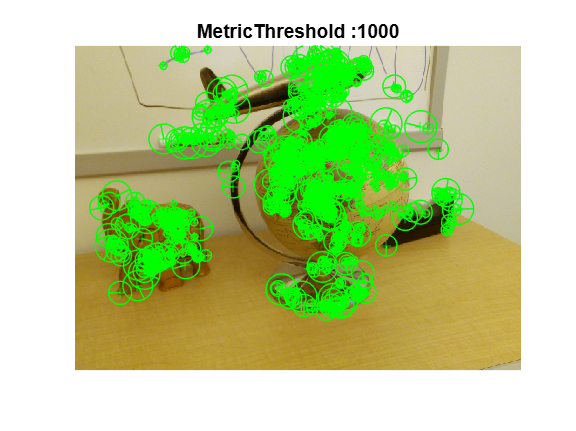


corners2 = detectSURFFeatures(rgb2gray(I2), 'MetricThreshold', threshold);
[features2, valid_corners2] = extractFeatures(rgb2gray(I2), corners2);
figure;
imshow(I2);
hold on;
plot(valid_corners2, 'showOrientation', true); % 'true' displays feature orientations
title(strcat('MetricThreshold : ',num2str(threshold)));
hold off;

Question 6

[indexPairs, matchmetric] = matchFeatures(features1, features2);

Question 7

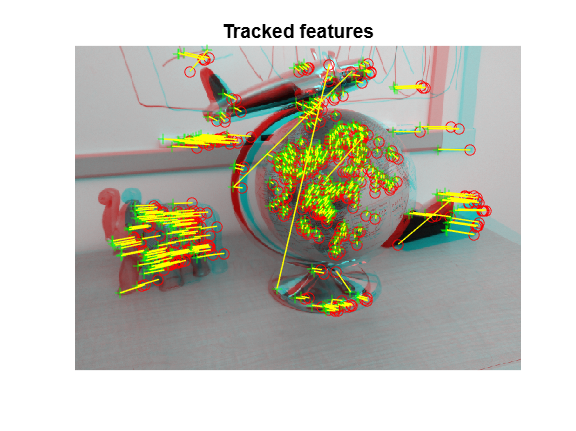

matchedPoints1 = valid_corners1(indexPairs(:,1));
matchedPoints2 = valid_corners2(indexPairs(:,2));

figure;
showMatchedFeatures(I1, I2, matchedPoints1, matchedPoints2);
title("Tracked features")

Question 8

load cp;
confidence = 99;
[E, epipolarInliers] = estimateEssentialMatrix(...
    matchedPoints1, matchedPoints2, cameraParams, 'Confidence', confidence);

inlierPoints1 = matchedPoints1(epipolarInliers, :);
inlierPoints2 = matchedPoints2(epipolarInliers, :);
showMatchedFeatures(I1, I2, inlierPoints1, inlierPoints2);
title(strcat("Epipolar inliers, Confidence : ", num2str(confidence)))

Question 9

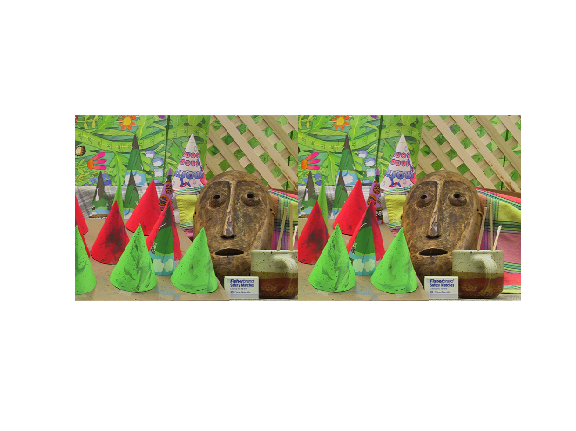

G=imread('im2.bmp'); 
D=imread('im6.bmp'); 
 
figure; 
imshowpair(G, D,'montage'); 

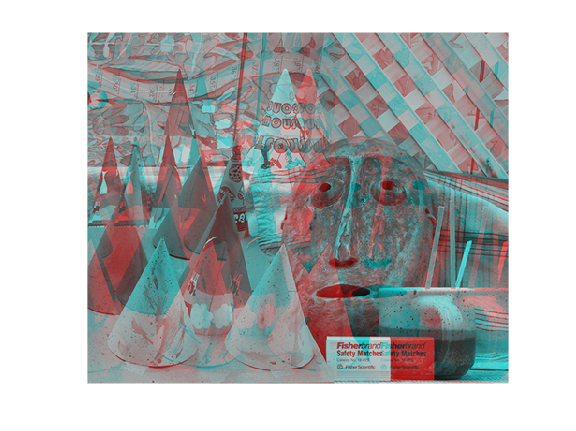


figure;  
imshow(stereoAnaglyph(rgb2gray(G),rgb2gray(D))); 

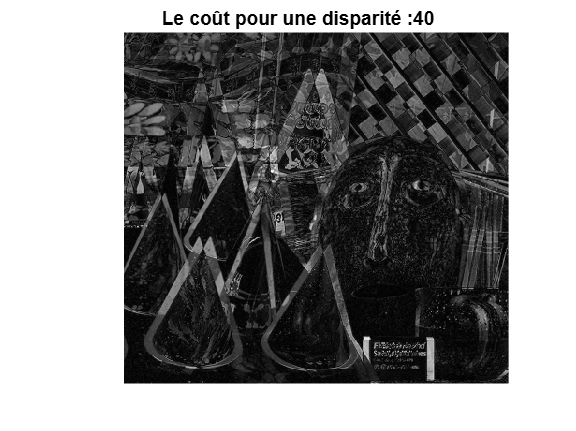


mindisp = 0;  
maxdisp = 64; 
[CoutG, CoutD] = calculate_cost(G, D, mindisp, maxdisp); 
figure; 
disp = 40; 
imshow(CoutG(:,:,disp), []);
title(strcat('Le coût pour une disparité : ', num2str(disp))); 

Question 10

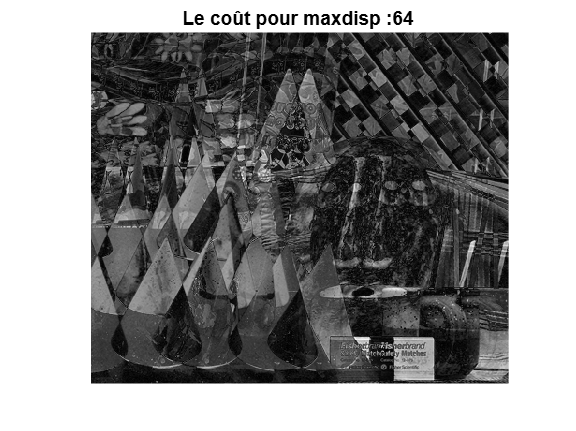

mindisp = 0;  
maxdisp = 64; 
[CoutG, CoutD] = calculate_cost(G, D, mindisp, maxdisp); 
figure; 
disp = 5; 
imshow(CoutG(:,:,disp), []);
title(strcat('Le coût pour maxdisp : ', num2str(maxdisp))); 

Question 11

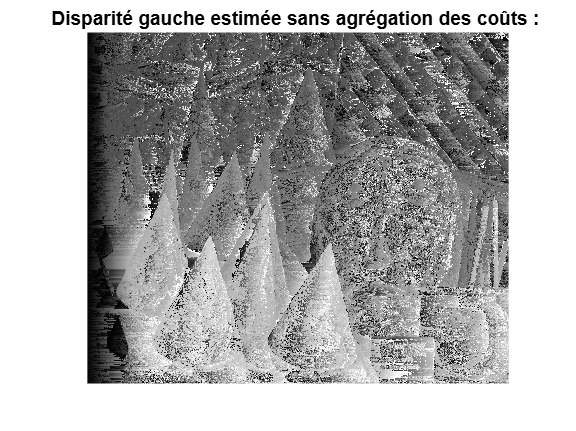

[DispG] = winner_takes_all(CoutG);
DispG = DispG + mindisp;
figure, imshow(DispG, [mindisp maxdisp]);
title(['Disparité gauche estimée sans agrégation des coûts : ']);

Question 12

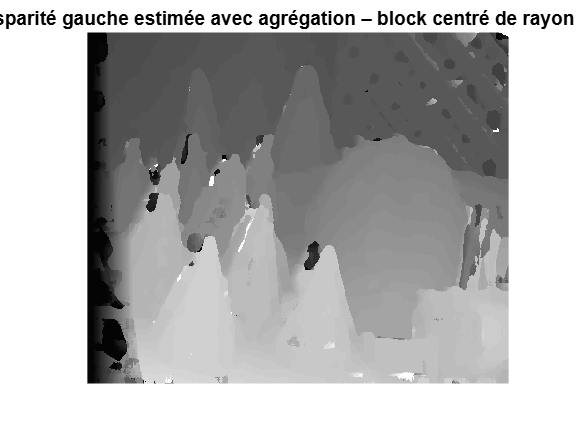

R = 5; % Rayon
CoutGa = aggregate_cost_block(CoutG, R);
[DispGa] = winner_takes_all(CoutGa);
DispGa = DispGa + mindisp;
figure, imshow(DispGa, [mindisp maxdisp]);
title(['Disparité gauche estimée avec agrégation – block centré de rayon R : 5' ]);

Question 13

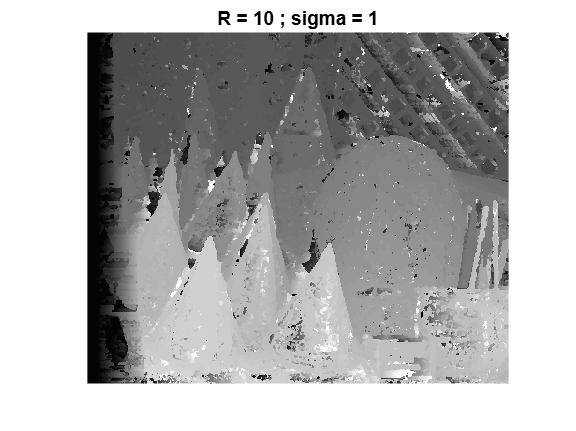

R=10; %Rayon 
S=1; %Sigma 
CoutGb = aggregate_cost_gauss(CoutG, R, S); 
[DispGb] = winner_takes_all(CoutGb); 
DispGb = DispGb + mindisp; 
figure, imshow(DispGb, [mindisp maxdisp]);

title_str = sprintf('R = %.0f ; sigma = %.0f', R, S);
% Disparité estimée avec agrégation gaussienne aggregation
title(title_str);

clear CoutGb; 